# Basic induction motor solver

%%motor operating conditions

    n=3;  	            %no. phases
    V1=239.6;             %rms 1 phase voltage
    p=4;                %no, poles
    f=50;               %operating frequency Hz
    Ns=120*f/p          %synchronous speed in rpm

Ns = 1500

    ws=2*pi*Ns/60      %in rad/s

ws = 157.0796

    R1=0.1;             %R1 resitsance in ohms
    
%Test paramaters
    
    %locked
    lockedrotortest=input('Locked rotor test?') %1 if yes

lockedrotortest = 1

    
    if lockedrotortest==1 %locked rotor test        
        
        V_test_locked=24/sqrt(3)       %vrms test phase voltage
        I_test_locked=12     %Irms test current
        P_dissipated_locked=225/3 %dissipated power W
        
        R2=(P_dissipated_locked/I_test_locked^2)-R1
        X=(V_test_locked^2-(P_dissipated_locked/I_test_locked)^2)^(1/2)/I_test_locked
    end

V_test_locked = 13.8564

I_test_locked = 12

P_dissipated_locked = 75

R2 = 0.4208

X = 1.0306

    
    %free
    
    freerotortest=input('free rotor test?') %1 if yes

freerotortest = 1

    
    if freerotortest==1 %locked rotor test        
        
        V_test_free=415/sqrt(3)        %vrms test phase voltage
        I_test_free=5        %Irms test current
        P_dissipated_free=180/3  %dissipated power W
        
        Rm=(V_test_free^2)/P_dissipated_free
        Xm=((V_test_free^2)/(I_test_free^2-(P_dissipated_free/V_test_free)^2))^(1/2)
    end

V_test_free = 239.6004

I_test_free = 5

P_dissipated_free = 60

Rm = 956.8056

Xm = 47.9803

    
%charcateristic plots

    syms W
    
    s=(ws-W)/ws;
    Torque_1=(V1^2*R2*s/ws)/((R1*s+R2)^2+s^2*X^2)

$$Torque\_1 = -\frac{332042441894361\,\left(W-50\,\pi \right)}{34359738368000\,\pi^{2}\,\left({\left(\frac{W-50\,\pi }{500\,\pi }-\frac{101}{240}\right)}^{2}+\frac{2447\,{\left(W-50\,\pi \right)}^{2}}{5760000\,\pi^{2}}\right)}$$

    Torque_tot=n*Torque_1

$$Torque\_tot = -\frac{996127325683083\,\left(W-50\,\pi \right)}{34359738368000\,\pi^{2}\,\left({\left(\frac{W-50\,\pi }{500\,\pi }-\frac{101}{240}\right)}^{2}+\frac{2447\,{\left(W-50\,\pi \right)}^{2}}{5760000\,\pi^{2}}\right)}$$

    P_tot=W*Torque_tot

$$P\_tot = -\frac{996127325683083\,W\,\left(W-50\,\pi \right)}{34359738368000\,\pi^{2}\,\left({\left(\frac{W-50\,\pi }{500\,\pi }-\frac{101}{240}\right)}^{2}+\frac{2447\,{\left(W-50\,\pi \right)}^{2}}{5760000\,\pi^{2}}\right)}$$

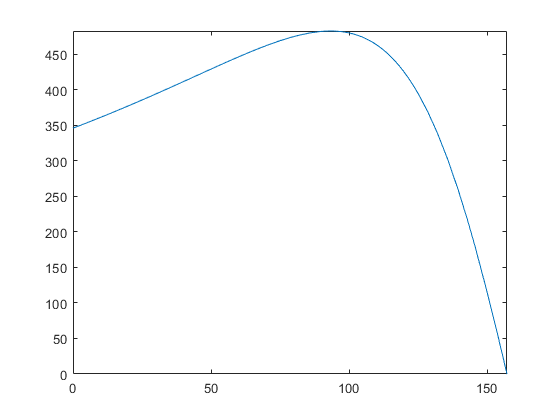

    fplot(Torque_tot,[0,ws])

    best_W=vpasolve(diff(Torque_tot)==0)

$$best\_W = \left(\begin{array}{c} 93.235755518231131381687873703354\\ 220.9235098407481924645764646246 \end{array}\right)$$

    best_torque=eval(subs(Torque_tot,W,best_W))

best_torque =   482.8295
 -586.0636


    p=eval(subs(P_tot,W,154.723))

p = 5.9968e+03